# Specify Stylesheet as a `StylesheetSourceString` Object

This example transforms the XML markup for countries and their capital cities into an HTML table. The example specifies the input stylesheet as a `matlab.io.xml.transform.StylesheetSourceString` object.

The examples uses the file `capitals.xml`.

Create a `StylesheetSourceString` object, `stylesheetObj`, to contain the XSL markup for the transformation.

import matlab.io.xml.transform.*
txt = ['<?xml version="1.0"?>' ...
    '<xsl:stylesheet version="1.0" xmlns:xsl="http://www.w3.org/1999/XSL/Transform">' ...
    '<xsl:template match="/">' ...
    '<html><body><table><tr><th>Country</th><th>Capital</th></tr>' ...
    '<xsl:for-each select="Countries/Country"><tr><td>' ...
    '<xsl:value-of select="Name"/></td><td>' ...
    '<xsl:value-of select="Capital"/></td></tr>' ...
    '</xsl:for-each></table></body></html></xsl:template></xsl:stylesheet>'];
stylesheetObj = StylesheetSourceString(txt);

Perform the transformation and provide `stylesheetObj` as the stylesheet, `capitals.xml` as the XML source, and `capitals.html` as the name of the output file.

transform(Transformer,"capitals.xml",stylesheetObj,"capitals.html");

Open `capitals.html` in a browser.

web("capitals.html")

Here is the HTML table:

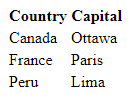

*Copyright 2020 The MathWorks, Inc.*